**Empirical evidence of *****sparse Gen-RKM***** from toy example in Pandey (2021)**

**Load dataset**

clear; clc;
load('toy.mat')

Xtr = toy(:, 1:2);

**Classical kernel PCA under RKM framework**

s =20;
params = {'rbf_func', 0.19, 'eta', 1};
[V, D, K] = singleview_skpca_rkm(Xtr, [], params, s, ...
    'PCA'); % classical kPCA

**Plot**

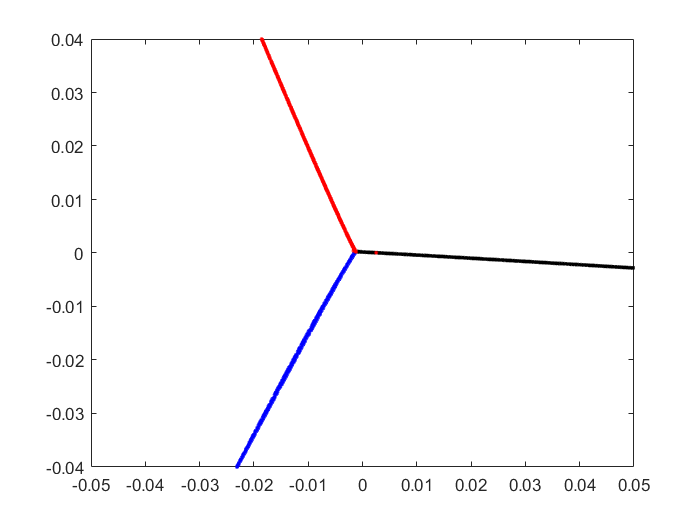

% Graph: 1-2nd PC
plot(V(toy(:, 3) == 1, 1), V(toy(:, 3) == 1, 2), 'b.', ...
    V(toy(:, 3) == 2, 1), V(toy(:, 3) == 2, 2), 'k.', ...
    V(toy(:, 3) == 3, 1), V(toy(:, 3) == 3, 2), 'r.')
xlim([-0.05, 0.05]);
ylim([-0.04, 0.04]);

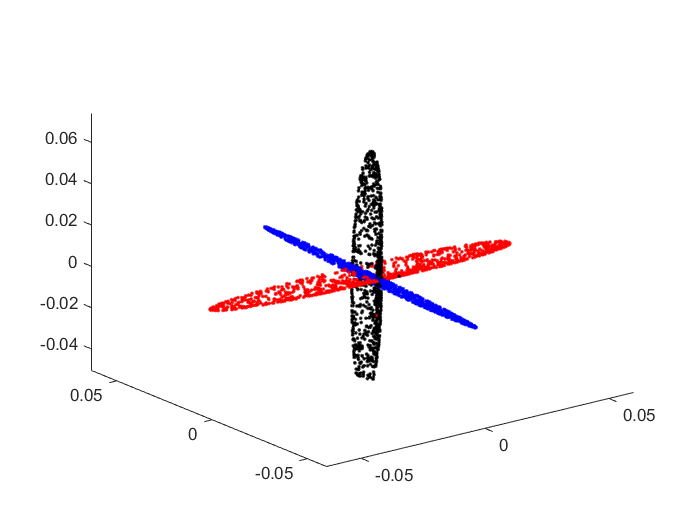


% Graph: 3-5th PC
plot3(V(toy(:, 3) == 1, 3), V(toy(:, 3) == 1, 4), V(toy(:, 3) == 1, 5), 'b.', ...
    V(toy(:, 3) == 2, 3), V(toy(:, 3) == 2, 4), V(toy(:, 3) == 2, 5), 'k.', ...
    V(toy(:, 3) == 3, 3), V(toy(:, 3) == 3, 4), V(toy(:, 3) == 3, 5), 'r.')

xlim([-0.1, 0.1]);
ylim([-0.1, 0.1]);
zlim([-0.1, 0.1]);

**Sparse kernel PCA under RKM framework**

*Truncated Power Method*

s =6;
params = {'rbf_func', 0.5, 'eta', 1, 'rhos', [0.3, 0.3, 0.3, 0.2, 0.15, 0.1], 'rf', []};
[Vs, Ds, Ks] = singleview_skpca_rkm(Xtr, [], params, s, 'TPower'); % sparse kPCA

**Plot**

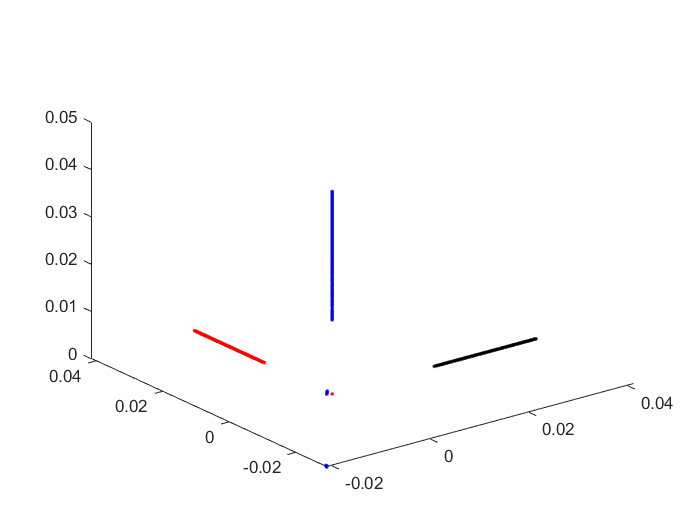

% Graph: 1-3rd PC
plot3(Vs(toy(:, 3) == 1, 1), Vs(toy(:, 3) == 1, 2), Vs(toy(:, 3) == 1, 3), 'b.', ...
    Vs(toy(:, 3) == 2, 1), Vs(toy(:, 3) == 2, 2), Vs(toy(:, 3) == 2, 3), 'k.', ...
    Vs(toy(:, 3) == 3, 1), Vs(toy(:, 3) == 3, 2), Vs(toy(:, 3) == 3, 3), 'r.')

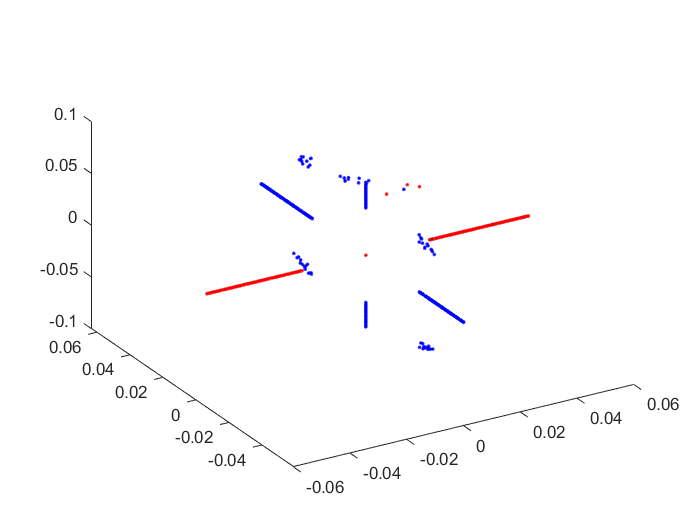


% Graph: 4-6th PC
plot3(Vs(toy(:, 3) == 1, 4), Vs(toy(:, 3) == 1, 5), Vs(toy(:, 3) == 1, 6), 'b.', ...
    Vs(toy(:, 3) == 2, 4), Vs(toy(:, 3) == 2, 5), Vs(toy(:, 3) == 2, 6), 'k.', ...
    Vs(toy(:, 3) == 3, 4), Vs(toy(:, 3) == 3, 5), Vs(toy(:, 3) == 3, 6), 'r.')

**Covariance matrix**

Vs(:, 1:3)'*Vs(:, 1:3) % not orthogonal

ans =     1.0000    0.0347   -0.0075
    0.0347    1.0000   -0.0106
   -0.0075   -0.0106    1.0000


V(:, 1:3)'*V(:, 1:3) % orthogonal

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000
